# Create GIF for Extended Kalman Filter

## Initilization

Initialize parameters for the simulation, setting up spacecraft and sensor characteristics. Then, run simulations for deadreckoning alone and deadreckoning with star tracker updates to store the resulting attitude errors.

% Simulation parameters
tstop = 50;
dt = 0.01;

% Spacecraft parameters
inertia_tensor_kg_m2 = [1 0 0;
    0 2 0;
    0 0 3];
initial_attitude_quat = [1 0 0 0];
initial_rate_radps = [0.05 0.05 0];

% Angular rate sensor
gyro_noise = 1e-5;

% Attitude sensor
star_tracker_noise = 1e-6;
time_between_measurements = .2;

% EKF Parameters
initial_state = [1 0 0 0];
initial_covariance = 1e-12;
measurement_covariance = eye(4);

%run first simulation
ad_method = 1; % Deadreckon subsystem variant
out = sim("spacecraft_model"); % Run simulation
dr_atterror_ts = out.logsout.getElement("Attitude Error (deg)").Values;
%deadreckon_att_err = simOut.attitude_error_deg;

%run second simulation
ad_method = 2; % Deadreckon with star tracker updates subsystem variant
out = sim("spacecraft_model"); % Run simulation
drst_atterror_ts = out.logsout.getElement("Attitude Error (deg)").Values;
%deadreckon_st_att_err = simOut.attitude_error_deg;

## EKF Runs

Run a series of simulations with the Extended Kalman Filter (EKF) using different process covariance values by changing the value of **pc_exponent** in a for-loop. Notice in the next section that you can interpolate between **pc_exponent** values so if you don't want to run 500 simulations to get all the absolute attitude error data for each value of **pc_exponent**, you can run a handful (~20, i.e. pc_exponent_array = -18:0) and just interpolate. In this example, I am getting data from -18:1:0, and will interpolate to get data in the range of -18:0.25:0. 

% Run the third simulation with the Extended Kalman Filter (EKF)
ad_method = 3; % EKF subsystem variant
pc_exponent_array = -18:0; % Exponents for process covariance to run
SavedEKF_runs = []; % Preallocate for EKF run data

% Loop over different process covariance values to simulate EKF with them
for pc_exponent = pc_exponent_array
    process_covariance = eye(4) * exp(pc_exponent); % Calculate process covariance
    out = sim("spacecraft_model"); % Run simulation
    ekf_atterror_ts = out.logsout.getElement("Attitude Error (deg)").Values;
    %ekf_att_err = simOut.attitude_error_deg; % Get attitude error from simulation output
    SavedEKF_runs = [SavedEKF_runs,ekf_atterror_ts.Data]; % Save data
    disp(['pc_exponent value: ',num2str(pc_exponent)]) % Display exponent value
end

pc_exponent value: -18
pc_exponent value: -17
pc_exponent value: -16
pc_exponent value: -15
pc_exponent value: -14
pc_exponent value: -13
pc_exponent value: -12
pc_exponent value: -11
pc_exponent value: -10
pc_exponent value: -9
pc_exponent value: -8
pc_exponent value: -7
pc_exponent value: -6
pc_exponent value: -5
pc_exponent value: -4
pc_exponent value: -3
pc_exponent value: -2
pc_exponent value: -1
pc_exponent value: 0


### Interpolation of Data

Interpolate the results from the EKF simulations to create smoother plots. This section generates an interpolated data set based on the initial EKF simulation results, generating clearer and more continuous visualizations. The dropdown allows you to change the interpolation method. 

Interpolate_pc_exponent_array = -18:0.25:0; % Interpolation range for pc_exponent
Interpolate_SavedEKF_runs = interp1(pc_exponent_array, SavedEKF_runs', Interpolate_pc_exponent_array, 'spline')'; % Interpolate the EKF run data using spline
TimeValue = ekf_atterror_ts.Time; % Time values for the plot

## GIF Creation

Generate and save an animated GIF that visually compares the attitude errors from deadreckoning, deadreckoning with star tracker, and the EKF over the range of process covariance exponents. When we save the first frame using the *exportgraphics()* function, we do not append this in case there's already a file with the same name as the variable **gifFileName**. You can adjust how many digits are shown in the legend by updating the value of %0.2f to %0.1f or %0.3f, for example.

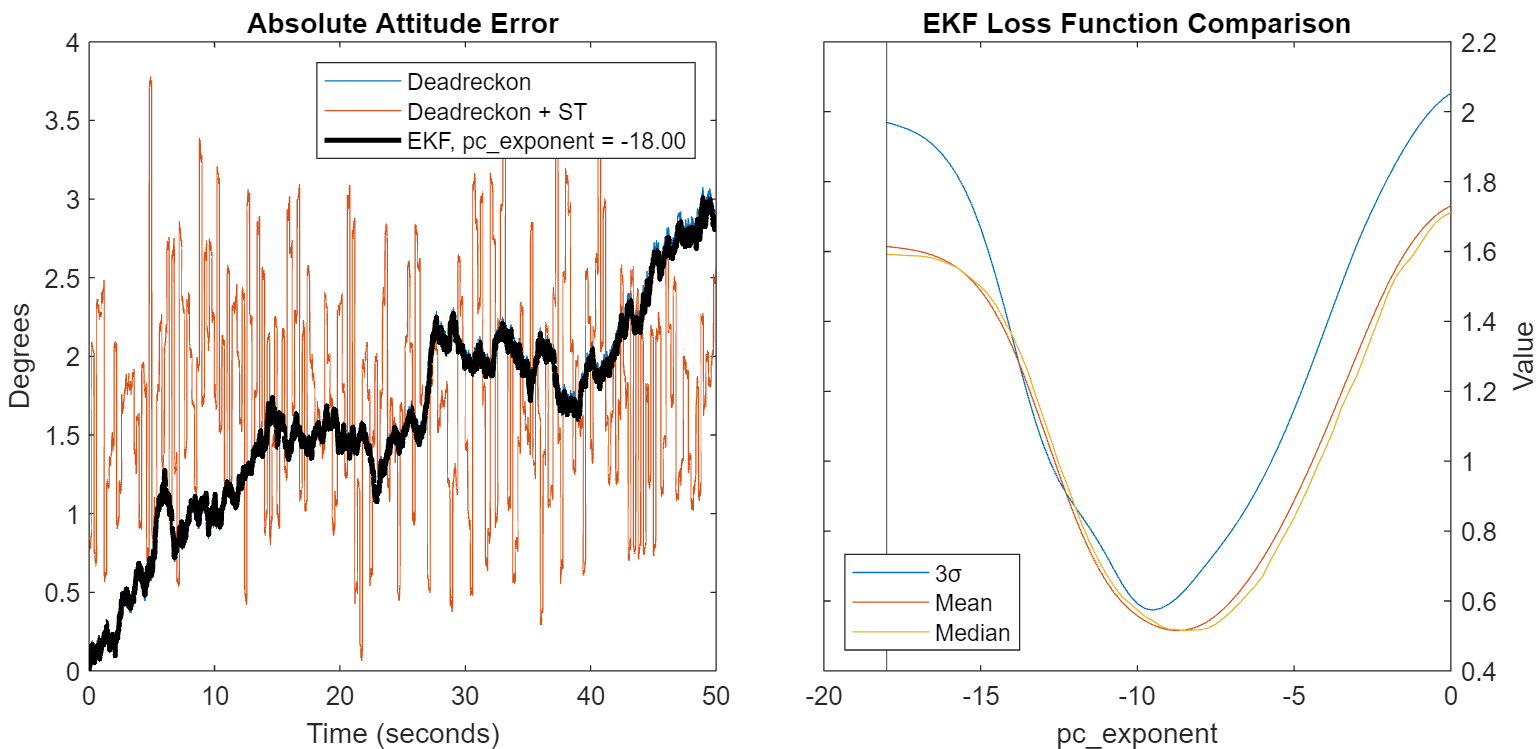

% Define the filename for the output GIF
gifFileName = "EKF_Comparison.gif";

% Set up a tiled layout for the plots
tileHandle = tiledlayout("horizontal");
tileHandle.Padding = 'tight';
tileHandle.TileSpacing = 'compact';

% Plot the deadreckoning and deadreckoning with star tracker errors on the left tile
nexttile
plot(dr_atterror_ts) % Plot deadreckoning attitude error
hold on
plot(drst_atterror_ts) % Plot deadreckoning with star tracker attitude error
LeftPlotHandle = plot(TimeValue, Interpolate_SavedEKF_runs(:,1), 'k', 'LineWidth', 2); % Plot the interpolated EKF run data
hold off
title('Absolute Attitude Error') % Title for the left plot
ylabel('Degrees') % Y-axis label for the left plot
LeftPlotLegend = legend('Deadreckon', 'Deadreckon + ST', sprintf('EKF, pc_exponent = %0.2f', Interpolate_pc_exponent_array(1)), 'Interpreter', 'none'); % Legend for the left plot

% Plot the EKF performance metrics on the right tile
nexttile
RightPlotHandle = plot(Interpolate_pc_exponent_array, 3*std(Interpolate_SavedEKF_runs), '-', ...
                       Interpolate_pc_exponent_array, mean(Interpolate_SavedEKF_runs), '-', ...
                       Interpolate_pc_exponent_array, median(Interpolate_SavedEKF_runs), '-'); % Plot the EKF statistics
RightPlotVertLine = xline(Interpolate_pc_exponent_array(1)); % Vertical line indicating the current pc_exponent
RightPlotHandle(1).Parent.YAxisLocation = "right"; % Move the Y-axis to the right side
ylabel('Value') % Y-axis label for the right plot
title('EKF Loss Function Comparison') % Title for the right plot
xlabel('pc_exponent') % X-axis label for both plots
RightPlotLegend = legend('3σ', 'Mean', 'Median', 'Interpreter', 'none', 'Location', 'southwest'); % Legend for the right plot

% Set the position and size of the tiled layout
tileHandle.Parent.Position = [257.666  152.333  862.666  420];

% Export the initial frame to the GIF. If "Append" were set to true, this would append rather than create a new .gif from scratch.
exportgraphics(tileHandle, gifFileName, "Append", false);

% Iterate over the interpolated EKF runs and update the plots, exporting each frame to the GIF
for ii = 1:size(Interpolate_SavedEKF_runs, 2)
    LeftPlotHandle.YData = Interpolate_SavedEKF_runs(:, ii); % Update the left plot data
    LeftPlotLegend.String = ["Deadreckon", "Deadreckon + ST", string(sprintf('EKF, pc_exponent = %0.2f', Interpolate_pc_exponent_array(ii)))]; % Update the legend text
    RightPlotVertLine.Value = Interpolate_pc_exponent_array(ii); % Update the vertical line position
    drawnow % Update the figure window
    exportgraphics(tileHandle, gifFileName, "Append", true); % Export the current frame to the GIF
end

% Iterate over the interpolated EKF runs in reverse order and update the plots, exporting each frame to the GIF
for jj = size(Interpolate_SavedEKF_runs, 2):-1:1
    LeftPlotHandle.YData = Interpolate_SavedEKF_runs(:, jj); % Update the left plot data
    LeftPlotLegend.String = ["Deadreckon", "Deadreckon + ST", string(sprintf('EKF, pc_exponent = %0.2f', Interpolate_pc_exponent_array(jj)))]; % Update the legend text
    RightPlotVertLine.Value = Interpolate_pc_exponent_array(jj); % Update the vertical line position
    drawnow % Update the figure window
    exportgraphics(tileHandle, gifFileName, "Append", true); % Export the current frame to the GIF
end